cd '/Users/dreyton/Desktop/BonePhantoms_US/phantom_3o25_30_fromBottom'

%read in image
image = load("imgData_CData_502.mat");
I0 = image.ImageData_filtered;


% Grayscale normalization
I0 = uint8(255*mat2gray(I0));
imshow(I0);
title('Original Image')

mid = floor(length(I0)/2)

mid = 425


%dynamic mask creation for I0
% Find the maximum value in the matrix and its index for I0
[maxValue, maxIndex] = max(I0(:));

% Convert the index to row and column subscripts
[row, col] = ind2sub(size(I0), maxIndex)

row = 94

col = 289


%create the mask
mask_I0 = zeros(size(I0))

mask_I0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


% Define the center point
%row = 175;
%col = 425;
center_point0 = [row,col]

center_point0 =    175   425



% Define the size of the square
square_size = 250;

% Calculate the indices of the square in the matrix
if row < square_size/2 % if it is at the edge
    row_indices = center_point0(1) : center_point0(1) + square_size;
    col_indices = center_point0(2) - floor(square_size/2) + 1 : center_point0(2) + floor(square_size/2);
else
    row_indices = center_point0(1) - floor(square_size/2) + 1 : center_point0(1) + floor(square_size/2);
    col_indices = center_point0(2) - floor(square_size/2) + 1 : center_point0(2) + floor(square_size/2);
    
end

% Assign the value of 1 to the square in the matrix
mask_I0(row_indices, col_indices) = 255;

imshow(mask_I0)

% Multiply image by mask

    % displays mask over original image 
    I0_b1 = I0;
    I0_b1(mask_I0>0) = 255;
    imshow(I0_b1);
    title('Mask burned into image')
    
    % displays masked image and blacks out everywhere else
    I0_b2 = I0;
    I0_b2(~mask_I0) = 0;
    imshow(I0_b2);
    
% crop image
tl_crop_image0 = center_point0 - square_size/2

tl_crop_image0 =     50   300


I0_RoI = imcrop(I0_b2, [tl_crop_image0(2) tl_crop_image0(1) square_size square_size])

I0_RoI = 251×251 uint8 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0   22   33   31   31   31   34   36   33   31   27   24   20   18   14   16   22   27   27   27   25   22   18   18   18   14    5    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0   22   34   34   34   34   34   34   33   29   25   24   22   22   22   20   20   18   20   22   22   20   20   18   16   14    7    0    0    0    0    0    0    0    0    0    0    0    2    5    0    0    0    0    0    0
    0    0    0    0   14   22   29   31   33   33   33   33   31   27   25   25   24   24   24   22   16    7   11   11   13   14   16   14   13   11   11    9    0    0    0    0    0    0    0    0    0    4    4  

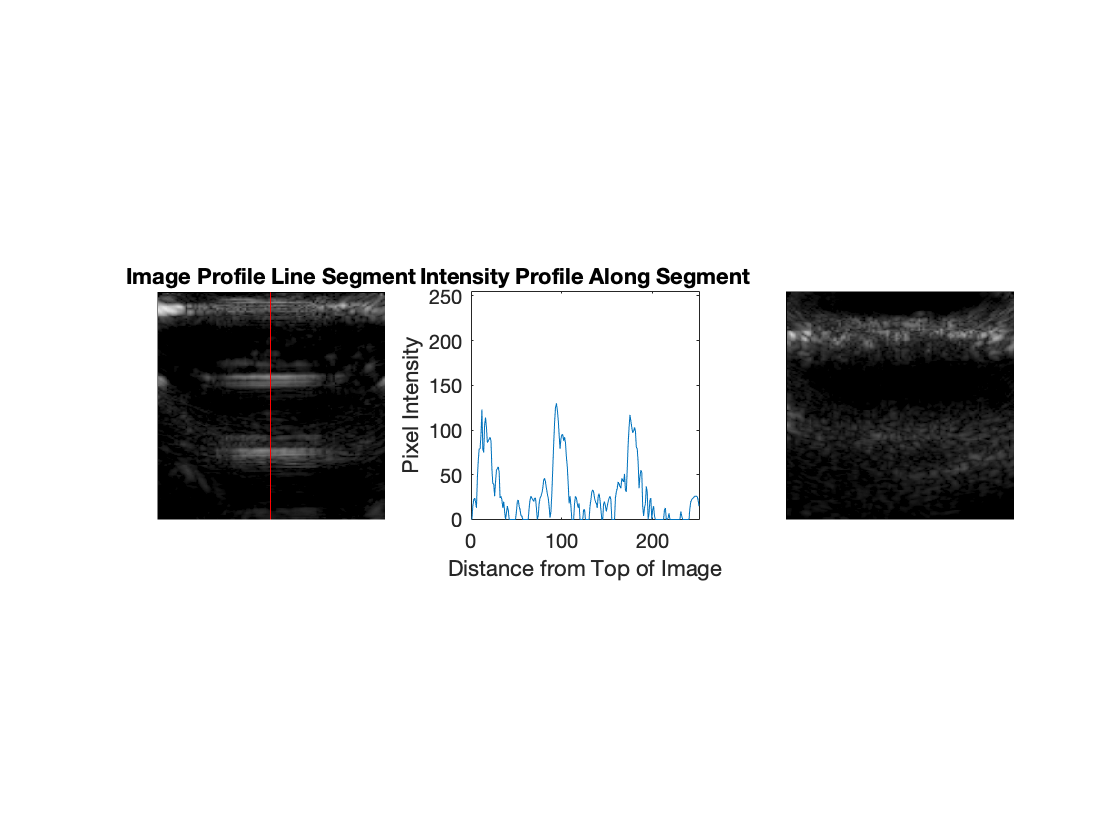

imshow(I0_RoI);


% Take average of the ROI
P = mean(I0_RoI(:));

% coordinate points for vertical line down middle
p1 = [1 , floor(length(I0_RoI)/2)];
p2 = [size(I0_RoI, 1), floor(length(I0_RoI)/2)];

% by x- and y-coordinates
x = [1, size(I0_RoI, 1)]

x =      1   251


y = [floor(length(I0_RoI)/2), floor(length(I0_RoI)/2)]

y =    125   125


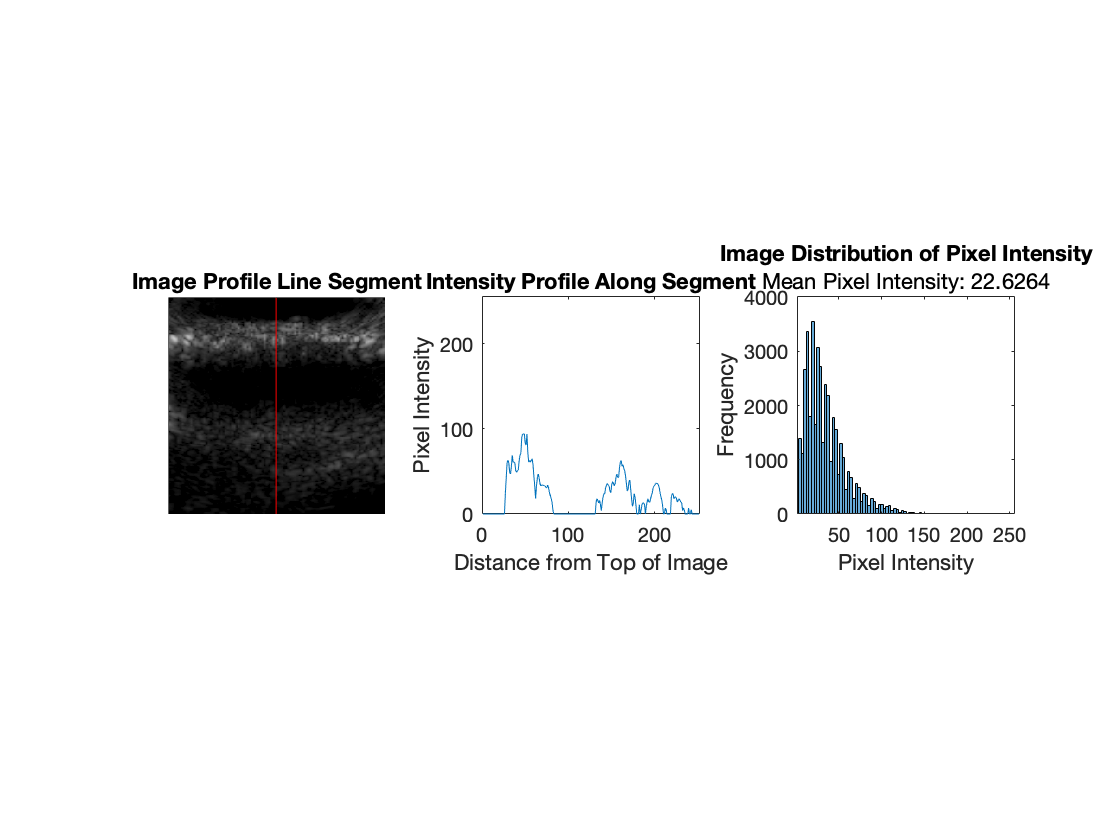


% show profile of line over image
figure
subplot(1,3,1)
imshow(I0_RoI)
hold on
plot(y,x, "Color", 'r')
ylim([0 size(I0_RoI, 1)])
xlim([0 length(I0_RoI)])
title('Image Profile Line Segment')
axis square
hold off

intensity = improfile(I0_RoI, y, x);

subplot(1,3,2)
plot(intensity)
ylim([0 255])
xlim([0 size(I0_RoI, 1)])
xlabel('Distance from Top of Image')
ylabel('Pixel Intensity')
title('Intensity Profile Along Segment')
axis square

idx = I0_RoI > 0;

subplot(1,3,3)
histogram(I0_RoI(idx))
xlim([1 255])
title('Image Distribution of Pixel Intensity', ['Mean Pixel Intensity: ',num2str(P)])
xlabel('Pixel Intensity')
ylabel('Frequency')
axis square

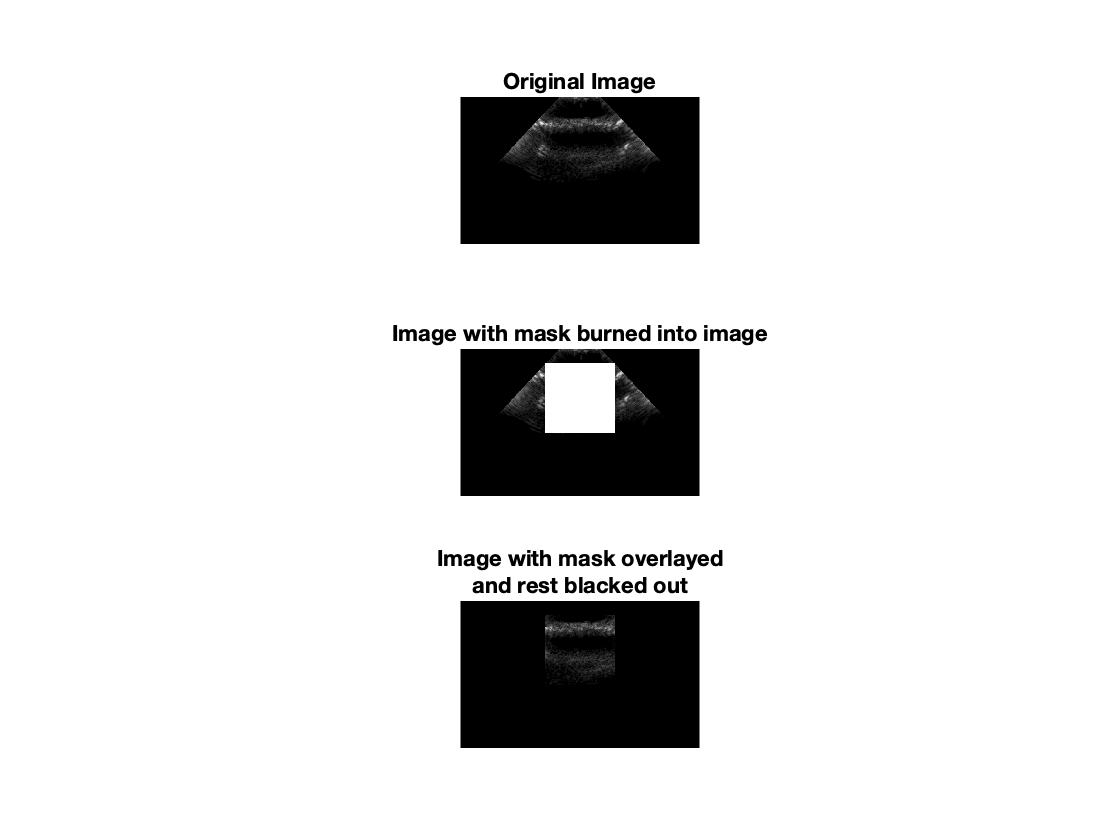

% Figure maker
figure
subplot(3,1,1)
imshow(I0)
title('Original Image')

subplot(3,1,2)
imshow(I0_b1)
title('Image with mask burned into image')

subplot(3,1,3)
imshow(I0_b2)
title({'Image with mask overlayed', 'and rest blacked out'})

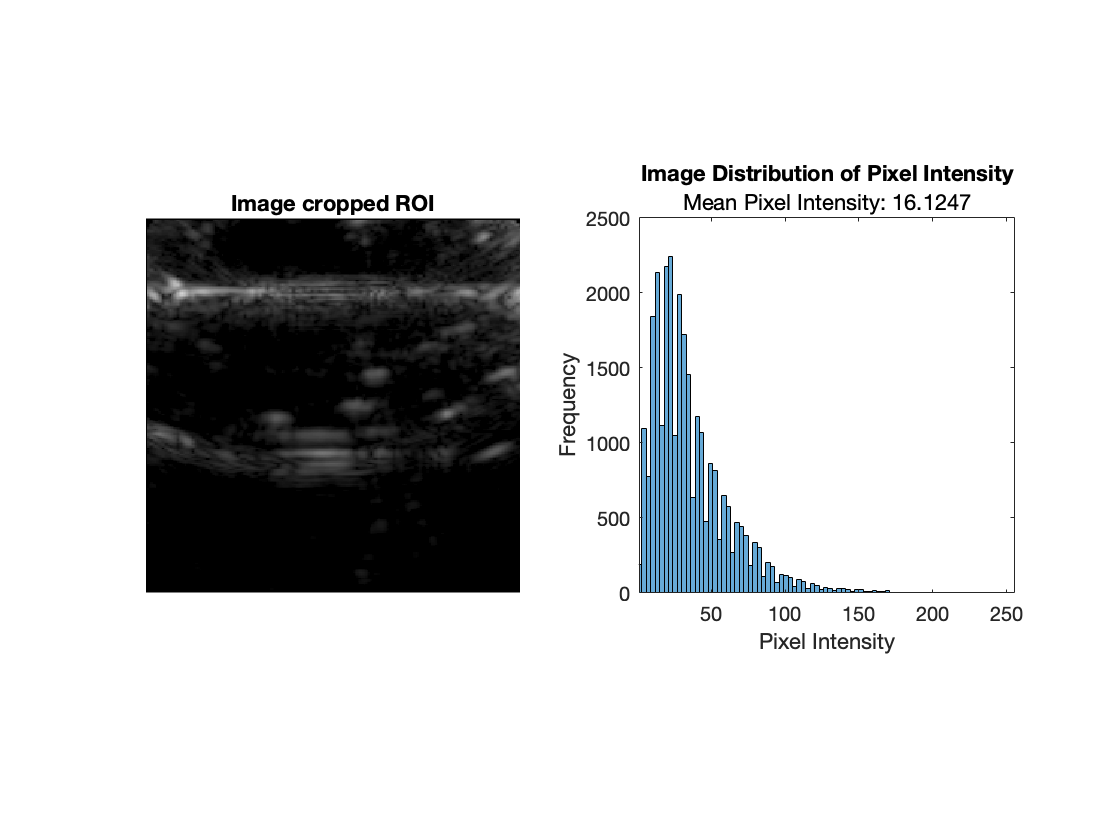

figure
subplot(1,2,1)
imshow(I0_RoI)
title('Image cropped ROI')


% filter out zeros from distribution
idx = I0_RoI > 0;

subplot(1,2,2)
histogram(I0_RoI(idx))
xlim([1 255])
title('Image Distribution of Pixel Intensity', ['Mean Pixel Intensity: ',num2str(P)])
xlabel('Pixel Intensity')
ylabel('Frequency')
axis square